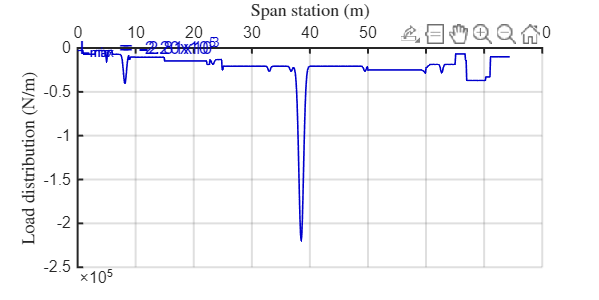

clear; clc; close all;

%% ========== INITIAL CONSTANTS AND SETUP ==========
g   = 9.81;    % gravitational acceleration [m/s^2]
dx  = 0.1;     % spatial discretization step [m]
fuselage_length = 74.4;  % [m]

x_stations = 0:dx:fuselage_length;    % station array
w_total    = zeros(size(x_stations)); % initialize weight distribution [kg/m]

%% ========== 1) BUILD WEIGHT DISTRIBUTION ==========
% 1A) Fuselage Shell (uniform)
fuselage_shell_weight = 21325.39;  % [kg]
idx_full_length = (x_stations >= 0 & x_stations <= fuselage_length);
w_total(idx_full_length) = w_total(idx_full_length) + ...
    fuselage_shell_weight / fuselage_length;

% 1B) Tail Group
tail_weight = 2981.50;  % [kg]
x_tail_start = fuselage_length - 7.63;  
x_tail_end   = fuselage_length;
idx_tail = (x_stations >= x_tail_start & x_stations <= x_tail_end);
if any(idx_tail)
    w_total(idx_tail) = w_total(idx_tail) + ...
        tail_weight / (x_tail_end - x_tail_start);
end

% 1C) Control Surfaces
ctrl_surf_weight = 2688.32;  % [kg]
idx_ctrl = (x_stations >= x_tail_start & x_stations <= x_tail_end);
if any(idx_ctrl)
    w_total(idx_ctrl) = w_total(idx_ctrl) + ...
        ctrl_surf_weight / (x_tail_end - x_tail_start);
end

% 1D) Landing Gear (nose + main gear lumps)
nose_gear_weight_kg = 2222.22;
main_gear_weight_kg = 20368.68;

nose_gear_sigma = 0.26;
nose_gear_gauss = exp(-0.5*((x_stations - 8.15) ./ nose_gear_sigma).^2);
nose_gear_gauss = nose_gear_gauss / sum(nose_gear_gauss*dx) * nose_gear_weight_kg;
w_total = w_total + nose_gear_gauss;

main_gear_sigma = 0.4;
main_gear_gauss = exp(-0.5*((x_stations - 38.5) ./ main_gear_sigma).^2);
main_gear_gauss = main_gear_gauss / sum(main_gear_gauss*dx) * main_gear_weight_kg;
w_total = w_total + main_gear_gauss;

% 1E) Electrical System (forward bay + small aft lump)
electrical_weight_kg = 690.75;
x_elec_start = 6; x_elec_end = 9;
idx_elec = (x_stations >= x_elec_start & x_stations <= x_elec_end);
if any(idx_elec)
    w_total(idx_elec) = w_total(idx_elec) + ...
        electrical_weight_kg/(x_elec_end - x_elec_start);
end

% Aft electronics near x=60 (Gaussian)
aft_elec_weight_kg = 300;
sigma_aft_elec = 0.3;
aft_elec_gauss = exp(-0.5*((x_stations - 60) ./ sigma_aft_elec).^2);
aft_elec_gauss = aft_elec_gauss / sum(aft_elec_gauss*dx) * aft_elec_weight_kg;
w_total = w_total + aft_elec_gauss;

% 1F) Hydraulic System
hydraulic_weight_total_kg = 920.23;
hyd_reservoir_lump = 1227.84 - hydraulic_weight_total_kg; 
hyd_lines_weight   = hydraulic_weight_total_kg - hyd_reservoir_lump;

% reservoir near x=33 (Gaussian)
x_hyd_center = 33; 
sigma_hyd    = 0.2;
hyd_center_gauss = exp(-0.5*((x_stations - x_hyd_center)./sigma_hyd).^2);
hyd_center_gauss = hyd_center_gauss / sum(hyd_center_gauss*dx) * hyd_reservoir_lump;
w_total = w_total + hyd_center_gauss;

% lines uniform from x=10 to x=60
idx_hyd_lines = (x_stations >= 10 & x_stations <= 60);
if any(idx_hyd_lines)
    w_total(idx_hyd_lines) = w_total(idx_hyd_lines) + ...
        (hyd_lines_weight / (60 - 10));
end

% 1G) Cabin Furnishings & Seating
n_first_class  = 0;
n_business     = 70; 
n_economy      = 430;
seat_wt_first  = 25; 
seat_wt_bus    = 22; 
seat_wt_eco    = 15; 
avg_passenger_kg = 42670.04 / 516;  % example

% First Class: x=6–12
W_first_total = n_first_class * (seat_wt_first + avg_passenger_kg);
idx_first = (x_stations >= 6 & x_stations <= 12);
if any(idx_first)
    w_total(idx_first) = w_total(idx_first) + ...
        W_first_total / (12 - 6);
end

% Business Class: x=12–25
W_bus_total = n_business * (seat_wt_bus + avg_passenger_kg);
idx_bus = (x_stations >= 7.8+1.07 & x_stations <= 7.8+1.07+13.93);
if any(idx_bus)
    w_total(idx_bus) = w_total(idx_bus) + ...
        W_bus_total / (25 - 12);
end

% Economy Class: x=25–650
W_eco_total = n_economy * (seat_wt_eco + avg_passenger_kg);
idx_eco = (x_stations >= 24.9 & x_stations <= 65);
if any(idx_eco)
    w_total(idx_eco) = w_total(idx_eco) + ...
        W_eco_total / (60 - 25);
end

% Overhead bins, monuments, etc.
furnishings_weight_kg = 8561.36 + 1610;
idx_furnish = (x_stations >= 6 & x_stations <= 60);
if any(idx_furnish)
    w_total(idx_furnish) = w_total(idx_furnish) + ...
        furnishings_weight_kg / (60 - 6);
end

% 1H) Lavatories + Galleys (lumps)
lav_galley_locs   = 7.8 + [1.07+13.93+0.5, ...
                           1.07+13.93+2.1+11.36+0.5, ...
                           1.07+13.93+2.1+11.36+2.1+10.62+0.5, ...
                           1.07+13.93+2.1+11.36+2.1+10.62+2.1+10.62+1];
lav_galley_wt_kg  = [300, 300, 300, 500];
for i = 1:length(lav_galley_locs)
    sigma_lav = 0.2;
    gauss_lav = exp(-0.5*((x_stations - lav_galley_locs(i)) ./ sigma_lav).^2);
    gauss_lav = gauss_lav / sum(gauss_lav*dx) * lav_galley_wt_kg(i);
    w_total = w_total + gauss_lav;
end

% 1I) Cargo (forward hold x=15–25, aft hold x=50–60)
cargo_fwd_weight_kg = 8717.6 * 0.5;
cargo_aft_weight_kg = 8717.6 * 0.5;
idx_cargo_fwd = (x_stations >= 15 & x_stations <= 25);
if any(idx_cargo_fwd)
    w_total(idx_cargo_fwd) = w_total(idx_cargo_fwd) + ...
        cargo_fwd_weight_kg / (25 - 15);
end
idx_cargo_aft = (x_stations >= 50 & x_stations <= 60);
if any(idx_cargo_aft)
    w_total(idx_cargo_aft) = w_total(idx_cargo_aft) + ...
        cargo_aft_weight_kg / (60 - 50);
end

% 1J) Flight Crew
pilot_wt_kg   = avg_passenger_kg;  
num_pilots    = 4;
cabin_crew_wt_kg = avg_passenger_kg; 
num_cabin_crew    = 12;

% Pilots near x=5 (small Gaussian)
pilot_sigma = 0.1;
pilot_gauss = exp(-0.5*((x_stations - 5)./pilot_sigma).^2);
pilot_gauss = pilot_gauss / sum(pilot_gauss*dx) * (pilot_wt_kg*num_pilots);
w_total = w_total + pilot_gauss;

% Cabin crew distributed from x=6 to x=60
crew_weight_total = cabin_crew_wt_kg * num_cabin_crew;
idx_crew = (x_stations >= 6 & x_stations <= 60);
if any(idx_crew)
    w_total(idx_crew) = w_total(idx_crew) + ...
        crew_weight_total / (60 - 6);
end

% 1K) APU in tail region
apu_weight_kg = 9350;
x_apu_start = 67; x_apu_end = 71;
idx_apu = (x_stations >= x_apu_start & x_stations <= x_apu_end);
if any(idx_apu)
    w_total(idx_apu) = w_total(idx_apu) + ...
        apu_weight_kg / (x_apu_end - x_apu_start);
end

% 1L) Air Conditioning ~ x=22.3–70.2
aircond_wt_kg = 19439.11;
x_ac_start = 22.3; x_ac_end = 70.2;
idx_ac = (x_stations >= x_ac_start & x_stations <= x_ac_end);
if any(idx_ac)
    w_total(idx_ac) = w_total(idx_ac) + ...
        aircond_wt_kg / (x_ac_end - x_ac_start);
end

% 1M) Anti-Icing near nose (x=1–3)
anti_icing_weight_kg = 859.8;
x_anti_start = 1; x_anti_end = 3;
idx_anti = (x_stations >= x_anti_start & x_stations <= x_anti_end);
if any(idx_anti)
    w_total(idx_anti) = w_total(idx_anti) + ...
        anti_icing_weight_kg / (x_anti_end - x_anti_start);
end

%% ========== PLOT & BASIC WEIGHT/CG CHECK ==========
% figure('Name','Inertial Load Distribution','NumberTitle','off');
% plot(x_stations, -w_total*g,'LineWidth',2);
% xlabel('Fuselage Station [m]');
% ylabel('Weight per Unit Length [N/m]');
% title('Aircraft Weight Distribution');
% grid on;

figure(1)

clf;

plot(x_stations, -w_total*g, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

txt1 = 'L_{max} = -2.81x10^3';
txt2 = 'L_{min} = -2.20x10^5';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [0/255 0/255 205/255], 'FontSize', 11)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Load distribution (N/m)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 500 250]);



W_total_kg = sum(w_total)*dx;
CG_total_m = sum(x_stations .* w_total)*dx / W_total_kg;
disp(['Total Mass = ', num2str(W_total_kg,'%8.1f'),' kg']);

Total Mass = 159308.2 kg


disp(['Fuselage Station CG = ', num2str(CG_total_m,'%4.2f'),' m']);

Fuselage Station CG = 41.89 m


W_total_N = W_total_kg * g

W_total_N = 1.5628e+06


%% ========== CASE 2: REACTION FORCES (FRONT & REAR SPAR) ABOUT NOSE ==========
% Suppose we treat the fuselage as a beam supported at two points:
%   x_sparFront, x_sparRear
% We find R_sparFront_kg, R_sparRear_kg so that sum of forces & moments = 0.

% Moment about x=0 (nose):
M_nose_kgm = sum(w_total .* x_stations)*dx;  % in [kg·m], if w_total is [kg/m]

% Example front & rear spar locations
LE = 26.5;
TE = 39.5;

x_sparFront = (LE + (TE-LE) * 0.2);    % old "Rf_loc"
x_sparRear  = (LE + (TE-LE) * 0.7);  % old "Rr_loc"

% Equations:
%   1) R_sparFront + R_sparRear = W_total_kg
%   2) x_sparFront*R_sparFront + x_sparRear*R_sparRear = M_nose_kgm

% Matrix form => [ -x_sparRear, -x_sparFront; -1, -1 ] * [R_rear; R_front] = [ -M; -W ]
A_spars = [ -x_sparRear, -x_sparFront;
            -1         , -1             ];
b_spars = [ -M_nose_kgm; -W_total_kg  ];

reactions_spar = A_spars \ b_spars;   % [ R_sparRear_kg ; R_sparFront_kg ] 
R_sparRear_kg  = reactions_spar(1);
R_sparFront_kg = reactions_spar(2);

disp('--- Spar Reaction Forces (mass, kg) about x=0 ---');

--- Spar Reaction Forces (mass, kg) about x=0 ---


disp(['R_sparRear_kg  = ', num2str(R_sparRear_kg,'%8.2f')]);

R_sparRear_kg  = 313477.69


disp(['R_sparFront_kg = ', num2str(R_sparFront_kg,'%8.2f')]);

R_sparFront_kg = -154169.47



R_sparFront_kg * g

ans = -1.5124e+06

R_sparRear_kg * g

ans = 3.0752e+06


%% ========== CASE 3 (MODIFIED): ONLY MAIN GEAR SUPPORTS WEIGHT & TAIL LOAD ==========

% Example load factor for on-ground (or maneuver)
loadFactor = 2.8199;  

% Total aircraft weight [N] under load factor
W_total_N = W_total_kg * g * loadFactor;

% Example tail load [N]; negative => downward
T_tail_N = -1.1202e+05;   % placeholder (downward 20,000 N, for example)

% Since only main gear carries the load:
%   Sum of vertical forces = 0  =>  R_main + (T_tail) + (-W_total) = 0
%   =>  R_main = W_total - T_tail
%      (Here, W_total is positive downward, T_tail negative => also downward,
%       so R_main must be upward = W_total - (negative) => W_total + |T_tail| )

R_mainGear_N = W_total_N - T_tail_N;

disp('--- Main Gear Reaction (No Nose Gear) ---');

--- Main Gear Reaction (No Nose Gear) ---


disp(['Load Factor = ', num2str(loadFactor), ' g']);

Load Factor = 2.8199 g


disp(['Tail Load   = ', num2str(T_tail_N,'%8.2f'), ' N  (negative => downward)']);

Tail Load   = -112020.00 N  (negative => downward)


disp(['Weight      = ', num2str(W_total_N,'%8.2f'), ' N']);

Weight      = 4406978.21 N


disp(['Main Gear Reaction = ', num2str(R_mainGear_N,'%8.2f'), ' N']);

Main Gear Reaction = 4518998.21 N




%% ========== CASE 4: TAILPLANE LOAD EQUILIBRIUM WITH TWO SPARS ==========
% Tailplane load T_tail_N acts at x_tail. 
% Sum of forces: R_sparFront_N + R_sparRear_N + T_tail_N = 0
% Sum of moments about x=0: R_sparFront_N*x_sparFront + R_sparRear_N*x_sparRear + T_tail_N*x_tail = 0

x_tail   = 72.2;    % [m]
T_tail_N = -54351;  % negative => downward
% Solve similarly:
% R_sparRear_N = -T_tail_N - R_sparFront_N, etc.

% For brevity, let's just show a solution form:
R_sparFront_N_tail = - T_tail_N * ((x_tail - x_sparRear)/(x_sparFront - x_sparRear));
R_sparRear_N_tail  = - T_tail_N - R_sparFront_N_tail;

disp('--- Tailplane Load Reactions on Two Spars ---');

--- Tailplane Load Reactions on Two Spars ---


disp(['Tail load = ', num2str(T_tail_N),' N (negative => downward)']);

Tail load = -54351 N (negative => downward)


disp(['R_sparFront_N = ', num2str(R_sparFront_N_tail,'%8.2f'),' N']);

R_sparFront_N = -306037.94 N


disp(['R_sparRear_N  = ', num2str(R_sparRear_N_tail,'%8.2f'),' N']);

R_sparRear_N  = 360388.94 N



%% ========== CASE 5: SHEAR & MOMENT TABLE EXAMPLE (TWO SPARS + TAIL LOAD) ==========
% Build a discrete "aeroLoad" array with lumps for front spar, rear spar, tail load
numStations  = length(x_stations);
aeroLoad_N   = zeros(1, numStations);

[~, idx_sparF] = min(abs(x_stations - x_sparFront));
[~, idx_sparR] = min(abs(x_stations - x_sparRear));
[~, idx_tailpt] = min(abs(x_stations - x_tail));

aeroLoad_N(idx_sparF) = R_sparFront_N_tail;
aeroLoad_N(idx_sparR) = R_sparRear_N_tail;
aeroLoad_N(idx_tailpt)= T_tail_N;

% Shear & Bending Moment
SF  = zeros(1,numStations);
dBM = zeros(1,numStations);
BM  = zeros(1,numStations);

SF(1) = aeroLoad_N(1);
for i = 2:numStations
    SF(i) = SF(i-1) + aeroLoad_N(i);
    dBM(i)= 0.5 * (SF(i) + SF(i-1)) * dx;
    BM(i) = BM(i-1) + dBM(i);
end

resultsTable = table(x_stations(:), aeroLoad_N(:), SF(:), dBM(:), BM(:), ...
    'VariableNames', {'Station','AeroLoad','SF','dBM','BM'});

disp('--- Shear & Moment Table (Tail Load + 2 Spar Reactions) ---');

--- Shear & Moment Table (Tail Load + 2 Spar Reactions) ---


disp(resultsTable);

    Station     AeroLoad          SF          dBM          BM     
    _______    ___________    ___________    ______    ___________

        0                0              0         0              0
      0.1                0              0         0              0
      0.2                0              0         0              0
      0.3                0              0         0              0
      0.4                0              0         0              0
      0.5                0              0         0              0
      0.6                0              0         0              0
      0.7                0              0         0              0
      0.8                0              0         0              0
      0.9                0              0         0              0
        1                

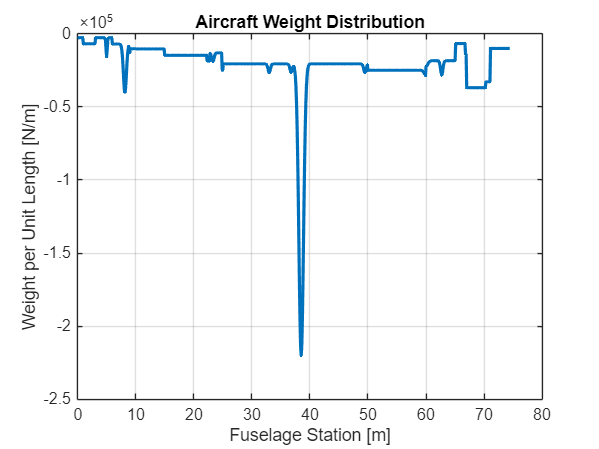


% %% ========== CASE 5b: WEIGHT + GEAR REACTION TABLE (Landing, Tail=0) ==========
% % If tail = 0, we can see how nose/main gear lumps combine with distribution.
% 
% % 1) Convert w_total [kg/m] -> discrete load in [N]
% distN_per_m = w_total * g * 1.0;  % (landing factor = 1.0 for example)
% distN_step  = distN_per_m * dx;   % each station chunk in [N]
% 
% % 2) Place lumps for nose & main gear
% gearLoadArray = zeros(1, numStations);
% [~, idxNose] = min(abs(x_stations - x_noseGear));
% [~, idxMain] = min(abs(x_stations - x_mainGear));
% gearLoadArray(idxNose) = R_noseGear_N;
% gearLoadArray(idxMain) = R_mainGear_N;
% 
% % 3) Total local load
% totalLoadN = distN_step + gearLoadArray;
% 
% % 4) Shear & Bending Moment
% SF2  = zeros(1,numStations);
% dBM2 = zeros(1,numStations);
% BM2  = zeros(1,numStations);
% 
% SF2(1) = totalLoadN(1);
% for i = 2:numStations
%     SF2(i)  = SF2(i-1) + totalLoadN(i);
%     dBM2(i) = 0.5*(SF2(i) + SF2(i-1))*dx;
%     BM2(i)  = BM2(i-1) + dBM2(i);
% end
% 
% % 5) Optional: moment arm about the fuselage CG
% x_CG      = CG_total_m;  % example
% armToCG   = x_stations - x_CG; 
% locMoment = totalLoadN .* armToCG;
% 
% resultsLanding = table(x_stations(:), ...
%     distN_step(:), ...
%     gearLoadArray(:), ...
%     totalLoadN(:), ...
%     SF2(:), ...
%     dBM2(:), ...
%     BM2(:), ...
%     armToCG(:), ...
%     locMoment(:), ...
%     'VariableNames', ...
%     {'Station','InertiaLoad','GearReactions','Total','SF','dBM','BM','CG_Arm','LocalMoment'});
% 
% disp('--- Table: Distribution + Gear Reactions (Tail=0 Landing) ---');
% disp(resultsLanding);



%% ========== PLOT & BASIC WEIGHT/CG CHECK ==========
figure('NumberTitle','off');
plot(x_stations, -w_total*g,'LineWidth',2);
xlabel('Fuselage Station [m]');
ylabel('Weight per Unit Length [N/m]');
title('Aircraft Weight Distribution');
grid on;


W_total_kg = sum(w_total)*dx;
CG_total_m = sum(x_stations .* w_total)*dx / W_total_kg;
disp(['Total Mass = ', num2str(W_total_kg,'%8.1f'),' kg']);

Total Mass = 159308.2 kg


disp(['Fuselage Station CG = ', num2str(CG_total_m,'%4.2f'),' m']);

Fuselage Station CG = 41.89 m


W_total_N = W_total_kg * g

W_total_N = 1.5628e+06